## Get Data

Provide the directory as a string to below function. In this case, we have a data directory '09-28-2021', where all the files are located.

if  ~exist('data','var')
    % parsing data
    animalType = '187_188';
    dataPath = dir(['../Fiberphotometry data/' animalType]);
    dataMap = readData(dataPath);
end

## Generate report for each day data

import mlreportgen.report.*
import mlreportgen.dom.*

Found Synapse note file: D:\lightPrj\Fiberphotometry data\187_188\09-08-2021\Notes.txt
read from t=0.00s to t=3017.09s
Found Synapse note file: D:\lightPrj\Fiberphotometry data\187_188\09-09-2021\Notes.txt
read from t=0.00s to t=2961.18s


R = Report('AnimalBehaviourReport','docx');
open(R);
for day = dataMap.keys
    dayText = Text(['Experiment Day: ' day{:}]);
    dayText.Bold = true;
    dayText.FontSize = '17pt';
    data = dataMap(day{:});
    add(R,dayText);
    add(R,data);
    addNormalizedData(data,R);
end
close(R);


## Normalized Data

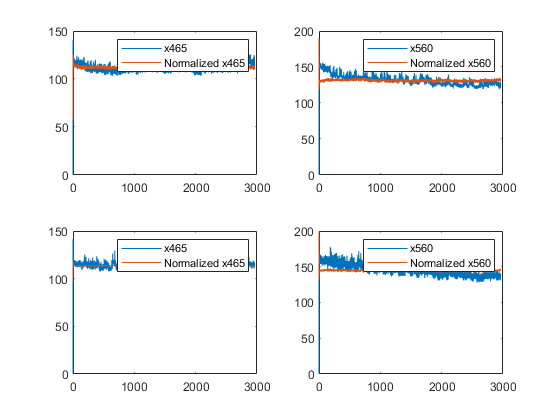

function addNormalizedData(data,R)
import mlreportgen.report.*

import mlreportgen.dom.*

signalFibPho1 = {'x405A','x465A','x560B'};
fs1 = data.streams.(signalFibPho1{1}).fs;
fs2 = data.streams.(signalFibPho1{2}).fs;
fs3 = data.streams.(signalFibPho1{3}).fs;
assert(fs1 == fs2, [signalFibPho1{1} 'and ' signalFibPho1{2} ' are in different rate']);
assert(fs1 == fs3, [signalFibPho1{1} 'and ' signalFibPho1{3} ' are in different rate']);

x405 = data.streams.(signalFibPho1{1}).data;
x465 = data.streams.(signalFibPho1{2}).data;
x560 = data.streams.(signalFibPho1{3}).data;

t0 = 1/fs1;
time = t0:t0:t0*length(x405);

[x465N1,x560N1] = getNormalizedSignal(x405,x465,x560);
subplot(2,2,1);
plot(time,x465);
hold on;
plot(time,x465N1);
legend('x465','Normalized x465');
hold off;
subplot(2,2,2);
plot(time,x560);
hold on;
plot(time,x560N1);
legend('x560','Normalized x560');
hold off;

signalFibPho2 = {'x405C','x465C','x560D'};
fs1 = data.streams.(signalFibPho2{1}).fs;
fs2 = data.streams.(signalFibPho2{2}).fs;
fs3 = data.streams.(signalFibPho2{3}).fs;
assert(fs1 == fs2, [signalFibPho2{1} 'and ' signalFibPho2{2} ' are in different rate']);
assert(fs1 == fs3, [signalFibPho2{1} 'and ' signalFibPho2{3} ' are in different rate']);

x405 = data.streams.(signalFibPho2{1}).data;
x465 = data.streams.(signalFibPho2{2}).data;
x560 = data.streams.(signalFibPho2{3}).data;

t0 = 1/fs1;
time = t0:t0:t0*length(x405);

[x465N1,x560N1] = getNormalizedSignal(x405,x465,x560);

subplot(2,2,3);
plot(time,x465);
hold on;
plot(time,x465N1);
legend('x465','Normalized x465');
hold off;
subplot(2,2,4);
plot(time,x560);
hold on;
plot(time,x560N1);
legend('x560','Normalized x560');
hold off;
add(R,Figure)
end

## Local functions

function dataMap = readData(dataPath)
dataMap = containers.Map;
for i = 1:length(dataPath)
    %data = TDTbin2mat('09-28-2021');
    data = TDTbin2mat.TDTbin2mat([dataPath(i).folder filesep dataPath(i).name]);
    if ~isempty(data)
        dataMap = [dataMap; containers.Map(dataPath(i).name,data)]; %# ok
    end
end
end

function [x465N,x560N] = getNormalizedSignal(x405,x465,x560)
arguments
    x405 single
    x465 single
    x560 single
end
x465N = getNormalSignal(x405,x465);
x560N = getNormalSignal(x405,x560);
end

function Y_fit = getNormalSignal(X,Y)
X1 = smooth(X);
Y1 = smooth(Y);
bls = polyfit(X1, Y1, 1);
Y_fit = bls(1).*X + bls(2);
end